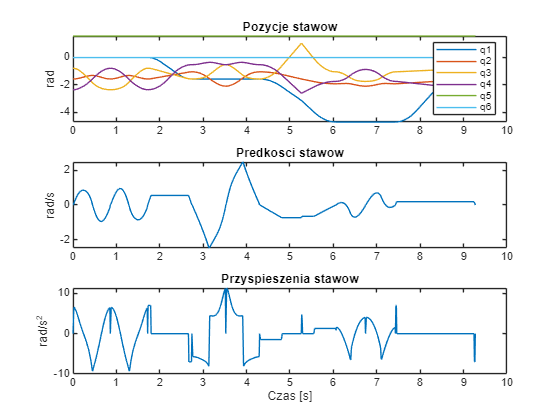

clc; clear; close all;


dt = 0.01;                     
ur3 = loadrobot("universalUR3","DataFormat","row","Gravity",[0 0 -9.81]);


v_L = 800/1000;    % [m/s]
a_L = 1600/1000;   % [m/s^2]

v_J = deg2rad(200);   % [rad/s]
a_J = deg2rad(400);   % [rad/s^2]
v_J_76 = deg2rad(300);  
a_J_76 = deg2rad(600); 
angles_deg.Punkt_orienta_1 = [-90, -60,  -90, -30,  90, 0];
angles_deg.Punkt_orienta_2 = [-90, -120, -30, -30,  90, 0];
angles_deg.Punkt_orienta_3 = [  0, -90, -135, -45,  90, 0];
angles_deg.Punkt_orienta_4 = [  0, -90,  -45, -135,  90, 0];
angles_deg.Punkt_orienta_5 = [-270, -120, -100, -50, 90, 0];
angles_deg.Punkt_orienta_6 = [-270, -110,  -60, -100, 90, 0];
angles_deg.Punkt_orienta_7 = [-180,  -90,   60, -150, 90, 0];
angles_deg.Punkt_orienta_8 = [-270, -110,  -60, -100, 90, 0];

fields = fieldnames(angles_deg);
for i = 1:numel(fields)
    angles.(fields{i}) = deg2rad(angles_deg.(fields{i}));
end

program = {
    struct('type','L','pt','Punkt_orienta_4');
    struct('type','L','pt','Punkt_orienta_3');
    struct('type','L','pt','Punkt_orienta_4');
    struct('type','J','pt','Punkt_orienta_1');
    struct('type','L','pt','Punkt_orienta_2');
    struct('type','L','pt','Punkt_orienta_1');
    struct('type','J','pt','Punkt_orienta_7');  
    struct('type','J','pt','Punkt_orienta_6');  
    struct('type','L','pt','Punkt_orienta_5');
    struct('type','L','pt','Punkt_orienta_8');
    struct('type','J','pt','Punkt_orienta_4');
    };


pointT = struct();
for i = 1:numel(fields)
    q = angles.(fields{i});
    pointT.(fields{i}) = getTransform(ur3, q, 'tool0');
end


startPt = program{1}.pt;
q_prev = angles.(startPt);
Tstart = pointT.(startPt);

all_q = q_prev(:)';         
all_qd = zeros(1,6);
all_qdd = zeros(1,6);
t_all = 0;
t_cursor = 0;

ik = inverseKinematics('RigidBodyTree', ur3);
weights = [0.5 0.5 0.5 1 1 1];
passThrough = {'Punkt_orienta_7'}; 

seg = 1;
while seg <= numel(program)
    item = program{seg};
    Tgoal = pointT.(item.pt);
    q_goal = angles.(item.pt);

    if strcmp(item.type,'J') && seg < numel(program) && ismember(item.pt, passThrough) ...
            && strcmp(program{seg+1}.type,'J')

        q_via = angles.(item.pt);
        q_next = angles.(program{seg+1}.pt);

            if strcmp(item.pt, 'Punkt_orienta_7') && strcmp(program{seg+1}.pt, 'Punkt_orienta_6')
            v_J_local = v_J_76;
            a_J_local = a_J_76;

        else
            v_J_local = v_J;
            a_J_local = a_J;
        end

        qPoints = [q_prev; q_via; q_next];
        q_temp = jointFullArc(qPoints, 1000);
        joint_dist = sum(vecnorm(diff(q_temp,1,1),2,2));

        t_acc = v_J_local / a_J_local;
        d_acc = 0.5 * a_J_local * t_acc^2;
        if joint_dist < 2*d_acc
            trajTime = 2 * sqrt(joint_dist / a_J_local);
        else
            trajTime = 2*t_acc + (joint_dist - 2*d_acc)/v_J_local;
        end

        N_total = max(round(trajTime / dt), 3);
        qArcUniform = jointFullArc(qPoints, N_total);
        s = trapezoidalScaling_joint(trajTime, a_J_local, v_J_local, size(qArcUniform,1));

        qt = zeros(length(s), size(qArcUniform,2));
        for j = 1:size(qArcUniform,2)
            qt(:,j) = interp1(linspace(0,1,size(qArcUniform,1)), qArcUniform(:,j), s, 'linear');
        end
        qd = [zeros(1,6); diff(qt)/dt];
        qdd = [zeros(1,6); diff(qd)/dt];

        if ~isempty(all_q) && norm(all_q(end,:) - qt(1,:)) < 1e-8
            qt(1,:) = []; qd(1,:) = []; qdd(1,:) = [];
        end

        nQ = size(qt,1);
        t_seg = t_cursor + (1:nQ)*dt;

        all_q   = [all_q; qt];
        all_qd  = [all_qd; qd];
        all_qdd = [all_qdd; qdd];
        t_all   = [t_all, t_seg];
        t_cursor = t_all(end);
        q_prev = all_q(end,:);
        Tstart = getTransform(ur3, q_prev, 'tool0');

        seg = seg + 2;
        continue;
    end

   
    if item.type == 'J'
        q_start = q_prev;
        q_end = q_goal;

        dq = abs(q_end - q_start);
        t_total_joint = zeros(6,1);
        for j = 1:6
            if dq(j) < 1e-6
                t_total_joint(j) = dt;
                continue;
            end
            t_acc_nom = v_J / a_J;
            d_acc_nom = 0.5 * a_J * t_acc_nom^2;
            if dq(j) < 2*d_acc_nom
                t_total_joint(j) = 2 * sqrt(dq(j) / a_J);
            else
                t_total_joint(j) = 2*t_acc_nom + (dq(j) - 2*d_acc_nom)/v_J;
            end
        end
        segTime = max(t_total_joint);
        segTime = max(segTime, dt);
        nSteps = max(ceil(segTime/dt),2);
        tvec = linspace(0, segTime, nSteps);

        qt = zeros(nSteps,6); qd = zeros(nSteps,6); qdd = zeros(nSteps,6);
        for j = 1:6
            q0 = q_start(j); q1 = q_end(j);
            sgn = sign(q1 - q0); dist = abs(q1 - q0);
            [s_vec, v_vec, a_vec] = jointTrapProfile(dist, segTime, v_J, a_J, tvec);
            qt(:,j)  = q0 + sgn * s_vec';
            qd(:,j)  = sgn * v_vec';
            qdd(:,j) = sgn * a_vec';
        end
        qt(end,:) = q_end(:)';
        qd(end,:) = zeros(1,6);
        qdd(end,:) = zeros(1,6);

    else
        [qt, qd, qdd, ~, ~, ~, segTime] = ...
            genLinearTCPSegment(ur3, q_prev, Tstart, Tgoal, v_L, a_L, dt, ik, weights);
        qt(end,:) = q_goal(:)';
        qd(end,:) = zeros(1,6);
        qdd(end,:) = zeros(1,6);
    end

    if ~isempty(all_q) && norm(all_q(end,:) - qt(1,:)) < 1e-8
        qt(1,:) = []; qd(1,:) = []; qdd(1,:) = [];
    end

    nQ = size(qt,1);
    t_seg = t_cursor + (1:nQ)*dt;

    all_q   = [all_q; qt];
    all_qd  = [all_qd; qd];
    all_qdd = [all_qdd; qdd];
    t_all   = [t_all, t_seg];
    t_cursor = t_all(end);
    q_prev = all_q(end,:);
    Tstart = getTransform(ur3, q_prev, 'tool0');
    seg = seg + 1;
end

q_full = all_q; qd_full = all_qd; qdd_full = all_qdd;
T_full = (0:size(q_full,1)-1)*dt;

TCP = zeros(size(q_full,1),6);
for i = 1:size(q_full,1)
    Tf = getTransform(ur3, q_full(i,:), 'tool0');
    TCP(i,1:3) = tform2trvec(Tf);
    TCP(i,4:6) = tform2eul(Tf, 'XYZ');
end
TCP_vel = [zeros(1,6); diff(TCP)/dt];
TCP_acc = [zeros(1,6); diff(TCP_vel)/dt];

% %% --- Animacja ---
% viewer = interactiveRigidBodyTree(ur3,'MarkerScaleFactor',0.2);
% fig = figure('Name','Ruch8MS - pass-through 7→6 ze zmienioną prędkością');
% r = rateControl(1/dt);
% for i = 1:size(q_full,1)
%     if ~isvalid(fig), break; end
%     viewer.Configuration = q_full(i,:);
%     waitfor(r);
% end

%% --- Wykresy ---
figure('Name','Trajektorie stawow');
subplot(3,1,1); plot(T_full, q_full); title('Pozycje stawow'); ylabel('rad'); legend('q1','q2','q3','q4','q5','q6');
subplot(3,1,2); plot(T_full, qd_full(:,2)); title('Predkosci stawow'); ylabel('rad/s');
subplot(3,1,3); plot(T_full, qdd_full(:,2)); title('Przyspieszenia stawow'); ylabel('rad/s^2'); xlabel('Czas [s]');

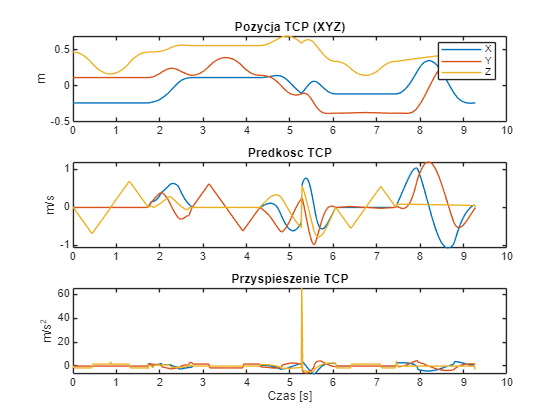


figure('Name','Trajektorie TCP');
subplot(3,1,1); plot(T_full, TCP(:,1:3)); title('Pozycja TCP (XYZ)'); ylabel('m'); legend('X','Y','Z');
subplot(3,1,2); plot(T_full, TCP_vel(:,1:3)); title('Predkosc TCP'); ylabel('m/s');
subplot(3,1,3); plot(T_full, TCP_acc(:,1:3)); title('Przyspieszenie TCP'); ylabel('m/s^2'); xlabel('Czas [s]');



function [qt, qd, qdd, TCP_pos, TCP_vel, TCP_acc, trajTime] = genLinearTCPSegment(ur3, q_start_guess, T_start, T_goal, v_max, a_max, dt, ik, weights)
    q_start_guess = q_start_guess(:)';
    p1 = tform2trvec(T_start); p2 = tform2trvec(T_goal);
    R1 = tform2rotm(T_start); R2 = tform2rotm(T_goal);

    dirVec = p2 - p1; d_TCP = norm(dirVec);
    if d_TCP < 1e-9
        qt = q_start_guess; qd = zeros(1,6); qdd = zeros(1,6);
        TCP_pos = p1; TCP_vel = zeros(1,3); TCP_acc = zeros(1,3);
        trajTime = 0; return;
    end
    uDir = dirVec/d_TCP;

    t_acc = v_max/a_max; d_acc = 0.5*a_max*t_acc^2;

    if d_TCP < 2*d_acc
        t_acc = sqrt(d_TCP/a_max); t_flat = 0; trajTime = 2*t_acc;
    else
        t_flat = (d_TCP - 2*d_acc)/v_max; trajTime = 2*t_acc + t_flat;
    end

    tvec = 0:dt:trajTime; n = numel(tvec);

    s = zeros(1,n); sd = zeros(1,n); sdd = zeros(1,n);

    for k = 1:n
        t = tvec(k);
        if t <= t_acc
            s(k) = 0.5*a_max*t^2; sd(k) = a_max*t; sdd(k) = a_max;
        elseif t <= t_acc + t_flat
            s(k) = d_acc + v_max*(t - t_acc); sd(k) = v_max; sdd(k)=0;
        else
            td = trajTime - t;
            s(k) = d_TCP - 0.5*a_max*td^2; sd(k) = a_max*td; sdd(k)=-a_max;
        end
    end
    s(end)=d_TCP; sd(end)=0; sdd(end)=0;

   
    TCP_pos = zeros(n,3); TCP_vel = zeros(n,3); TCP_acc = zeros(n,3);
    q1 = rotm2quat(R1); q2 = rotm2quat(R2);
    q1 = q1/norm(q1); q2 = q2/norm(q2);

    qt = zeros(n,6); prevQ = q_start_guess;
    for k = 1:n
        uk = min(max(s(k)/d_TCP,0),1);
        pos_k = p1 + uk*dirVec;
        qk = slerpQuat(q1,q2,uk); Rk = quat2rotm(qk);
        Tk = trvec2tform(pos_k)*rotm2tform(Rk);
        [qsol, ~] = ik('tool0', Tk, weights, prevQ);
        qt(k,:) = qsol; prevQ = qsol;
        TCP_pos(k,:) = pos_k; TCP_vel(k,:) = sd(k)*uDir; TCP_acc(k,:) = sdd(k)*uDir;
    end

    qd = zeros(n,6); qdd = zeros(n,6);
    if n>1
        qd(2:end,:) = diff(qt)/dt; qd(1,:)=zeros(1,6); qd(end,:)=zeros(1,6);
        qdd(2:end,:) = diff(qd)/dt; qdd(1,:)=zeros(1,6); qdd(end,:)=zeros(1,6);
    end
end

function qout = slerpQuat(q0,q1,t)
    if t<=0, qout=q0; return; end
    if t>=1, qout=q1; return; end
    q0 = q0/norm(q0); q1=q1/norm(q1);
    dotp = dot(q0,q1);
    if dotp <0, q1=-q1; dotp=-dotp; end
    dotp = min(max(dotp,-1),1);
    if dotp>0.9995, qout=(1-t)*q0+t*q1; qout=qout/norm(qout); return; end
    theta0 = acos(dotp); theta = theta0*t;
    s0 = cos(theta) - dotp*sin(theta)/sin(theta0);
    s1 = sin(theta)/sin(theta0);
    qout = s0*q0+s1*q1; qout=qout/norm(qout);
end

function [s_vec, v_vec, a_vec] = jointTrapProfile(distance, T, v_max, a_max, tvec)
    N = numel(tvec); s_vec=zeros(1,N); v_vec=zeros(1,N); a_vec=zeros(1,N);
    if distance<1e-12, return; end
    D = T^2 - 4*distance/a_max;
    if D<0, t1 = min(T/2, v_max/a_max); else t1=(T-sqrt(D))/2; t1=min(max(t1,0),T/2); end
    v_peak=a_max*t1;
    if v_peak>v_max, t1=v_max/a_max; tf=T-2*t1; if tf<0, t1=T/2; v_peak=a_max*t1; tf=0; end; else tf=T-2*t1; end
    d_acc=0.5*a_max*t1^2;
    for idx=1:N
        t=tvec(idx);
        if t<=0, s=0; v=0; a=0;
        elseif t<t1, s=0.5*a_max*t^2; v=a_max*t; a=a_max;
        elseif t<t1+tf, s=d_acc+v_peak*(t-t1); v=v_peak; a=0;
        elseif t<=T, td=t-(t1+tf); s=d_acc+v_peak*tf+v_peak*td-0.5*a_max*td^2; v=v_peak-a_max*td; a=-a_max;
        else, s=distance; v=0; a=0; end
        s_vec(idx)=min(max(s,0),distance); v_vec(idx)=v; a_vec(idx)=a;
    end
    s_vec(end)=distance; v_vec(end)=0; a_vec(end)=0;
end

function qArc = jointFullArc(qPoints, N)
    
    M = size(qPoints, 1);
    totalDist = 0;
    segLen = zeros(M-1,1);

    for i = 1:M-1
        segLen(i) = norm(qPoints(i+1,:) - qPoints(i,:));
        totalDist = totalDist + segLen(i);
    end

    
    if totalDist < 1e-12
        qArc = repmat(qPoints(1,:), max(1,N), 1);
        return;
    end

    qArc = [];
    for i = 1:M-1
        Ni = max(round(N * segLen(i) / totalDist),1);
        qPart = jointLinearInterp(qPoints(i,:), qPoints(i+1,:), Ni+1);
        if i > 1
            qPart = qPart(2:end,:);
        end
        qArc = [qArc; qPart];
    end
end

function qLin = jointLinearInterp(q1, q2, N)
    qLin = zeros(N, length(q1));
    for i = 1:length(q1)
        qLin(:,i) = linspace(q1(i), q2(i), N)';
    end
end

function s = trapezoidalScaling_joint(trajTime, a_max, v_max, N)
    
    dt = trajTime / (N - 1);
    t = linspace(0, trajTime, N);

    t_acc = v_max / a_max;
    d_acc = 0.5 * a_max * t_acc^2;

    if trajTime < 2*t_acc
        t_acc = sqrt(trajTime * a_max / 2);
        t_flat = 0;
    else
        t_flat = trajTime - 2*t_acc;
    end

    s = zeros(size(t));
    for i = 1:length(t)
        if t(i) <= t_acc
            s(i) = 0.5 * a_max * t(i)^2;
        elseif t(i) <= (t_acc + t_flat)
            s(i) = d_acc + v_max * (t(i) - t_acc);
        else
            t_dec = t(i) - (t_acc + t_flat);
            s(i) = d_acc + v_max * t_flat + v_max * t_dec - 0.5 * a_max * t_dec^2;
        end
    end

    
    s = s / max(s);
end


rawText = fileread("Shoulder_R8_Wolno-000.txt");
lines = strsplit(rawText, newline);
lines = lines(~startsWith(strtrim(lines), "//")); % usuń komentarze

tempFile = 'imu_clean.txt';
fid = fopen(tempFile, 'w');
fprintf(fid, '%s\n', lines{:});
fclose(fid);

imu = readtable(tempFile, 'FileType','text');

varsToConvert = {'PacketCounter','SampleTimeFine','Acc_X','Acc_Y','Acc_Z','Gyr_X','Gyr_Y','Gyr_Z'};
for v = varsToConvert
    if ismember(v{1}, imu.Properties.VariableNames)
        imu.(v{1}) = double(imu.(v{1}));
    end
end

dt_imu = 1/400;  
t_imu = (0:dt_imu:(height(imu)-1)*dt_imu)';

acc_data = ([imu.Acc_X, imu.Acc_Y, imu.Acc_Z]/9.81-1)/2*16;
gyr_data = [imu.Gyr_X, imu.Gyr_Y, imu.Gyr_Z];

shiftSamples = 0;
acc_data_shifted = circshift(acc_data, shiftSamples);
gyr_data_shifted = circshift(gyr_data, shiftSamples);

acc_data_shifted(1:shiftSamples,:) = NaN;
gyr_data_shifted(1:shiftSamples,:) = NaN;
t_imu_shifted = t_imu;


offset = 2.21;

gZ = gyr_data_shifted(:,3); 
aZ = acc_data_shifted(:,3); 

firstNonNaN_g = find(~isnan(gZ),1,'first');
firstNonNaN_a = find(~isnan(aZ),1,'first');
if isempty(firstNonNaN_g), firstNonNaN_g = 1; end
if isempty(firstNonNaN_a), firstNonNaN_a = 1; end
gZ_init = gZ; aZ_init = aZ;
gZ_init(1:firstNonNaN_g-1) = gZ_init(firstNonNaN_g);
aZ_init(1:firstNonNaN_a-1) = aZ_init(firstNonNaN_a);


dt_kf = dt; 


N = length(gZ_init);


idle_end = min(max(5, offset-1), floor(N/8));
if idle_end < 5
    idle_end = 5;
end
idle_end = min(idle_end, N);
gZ_idle = gZ_init(1:idle_end);
aZ_idle = aZ_init(1:idle_end);


V_g = max(0.01,var(gZ_idle)); 
V_a = max(0.01,var(aZ_idle));


W_g = (0.5)^2;   
W_a = (0.5)^2;   

xpost_g = zeros(N,1);
Ppost_g = zeros(N,1);
xpost_a = zeros(N,1);
Ppost_a = zeros(N,1);

xpost_g(1) = gZ_init(1);
Ppost_g(1) = 1;
xpost_a(1) = aZ_init(1);
Ppost_a(1) = 1;

A = 1; C = 1;

for k = 2:N
    xpri = A * xpost_g(k-1);
    Ppri = A * Ppost_g(k-1) * A' + V_g;
    yk = gZ_init(k);
    S = C * Ppri * C' + W_g;
    K = Ppri * C' / S;
    eps = yk - C * xpri;
    xpost_g(k) = xpri + K * eps;
    Ppost_g(k) = Ppri - K * S * K';

    xpri = A * xpost_a(k-1);
    Ppri = A * Ppost_a(k-1) * A' + V_a;
    yk = aZ_init(k);
    S = C * Ppri * C' + W_a;
    K = Ppri * C' / S;
    eps = yk - C * xpri;
    xpost_a(k) = xpri + K * eps;
    Ppost_a(k) = Ppri - K * S * K';
end

filtered_gZ = xpost_g;
filtered_aZ = xpost_a;

filtered_gZ(1:shiftSamples) = NaN;
filtered_aZ(1:shiftSamples) = NaN;

figure('Name','qd_{TCP} vs IMU (surowe + Kalman)','Units','normalized','Position',[0.2 0.2 0.65 0.6]);
subplot(1,2,1)
hold on;

h1 = plot(T_full, rad2deg(qd_full(:,2)), '-', 'Color',[0 0 0], 'LineWidth', 10);
h2 = plot((t_imu_shifted - offset), rad2deg(gyr_data_shifted(:,3)), '--', 'Color',[0.2 0.6 0.9], 'LineWidth', 10);
h3 = plot((t_imu_shifted - offset), rad2deg(filtered_gZ), '-', 'Color',[0.9 0.55 0.0], 'LineWidth', 7.5);

xlabel('Czas [s]', 'FontSize', 35);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35);
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','ω z zastosowaniem filtru Kalmana','Location', 'Northeast', 'FontSize', 20);
grid on;
xlim([0 9.27]);
set(gca, 'FontSize', 30);
hold off;


w_ref = qd_full(:,2);
t_ref = T_full(:);

w_meas = filtered_gZ(:);
t_meas = (t_imu_shifted(:) - offset);

valid_ref = ~isnan(w_ref) & ~isnan(t_ref);
valid_meas = ~isnan(w_meas) & ~isnan(t_meas);
w_ref = w_ref(valid_ref);
t_ref = t_ref(valid_ref);
w_meas = w_meas(valid_meas);
t_meas = t_meas(valid_meas);

commonRange = (t_ref >= min(t_meas)) & (t_ref <= max(t_meas));
t_ref_common = t_ref(commonRange);
w_ref_common = w_ref(commonRange);

w_meas_interp = interp1(t_meas, w_meas, t_ref_common, 'linear', 'extrap');

N = min(length(w_ref_common), length(w_meas_interp));
w_ref_common = w_ref_common(1:N);
w_meas_interp = w_meas_interp(1:N);

w_ref_common = w_ref_common(:);
w_meas_interp = w_meas_interp(:);

I_omega = mean(abs(w_ref_common - w_meas_interp), 'omitnan');
fprintf('Wartość funkcji celu I(ω): %.6f [°/s]\n', rad2deg(I_omega));

Wartość funkcji celu I(ω): 5.602757 [°/s]


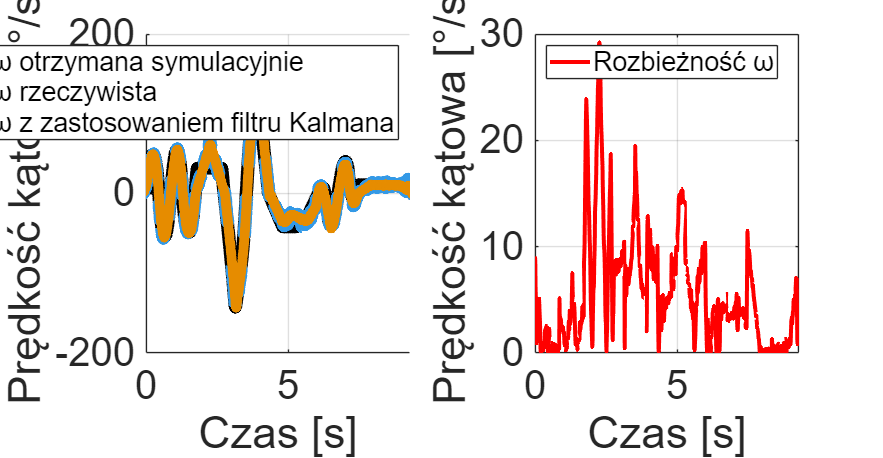


e_omega = w_meas_interp - w_ref_common;
e_omega(isnan(e_omega)) = 0;

subplot(1,2,2)
plot(t_ref_common, rad2deg(abs(e_omega)), 'r', 'LineWidth', 3);
grid on;
legend('Rozbieżność ω','Location', 'Northwest', 'FontSize', 20);
xlabel('Czas [s]', 'FontSize', 35);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 30);
set(gca, 'FontSize', 30);
xlim([0 9.27]);